nec = NECPA271Sim
hp = HPZ24xSim
rift = RiftSim
cc = ColorConversionClass;



disp = rift;

XYZ_d65 = [94.811 100 107.304];
XYZ_target = XYZ_d65 * 0.0210 / 2 / 100

XYZ_target =     0.0100    0.0105    0.0113



rgb_lin = disp.XYZ2RGB_lin(XYZ_target)

rgb_lin =     0.6762
    0.5823
    0.5926


vec = disp.RGB_lin2vec(rgb_lin);

% lit the light
s = ols.FWD_vec2spdC(vec);
mea = ol.setColumn1024GammaandMeasure(vec,cs);
mea.XYZ

ans =     0.0093    0.0102    0.0091


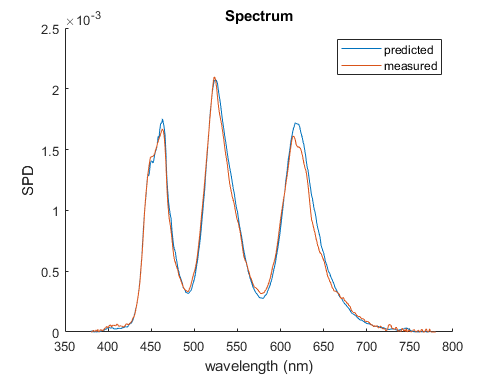


clf
hold on
s.plot
mea.plot
legend('predicted','measured')

y = cc.cmf(:,3)

y =     0.0000
    0.0001
    0.0004
    0.0012
    0.0040
    0.0116
    0.0230
    0.0380
    0.0600
    0.0910


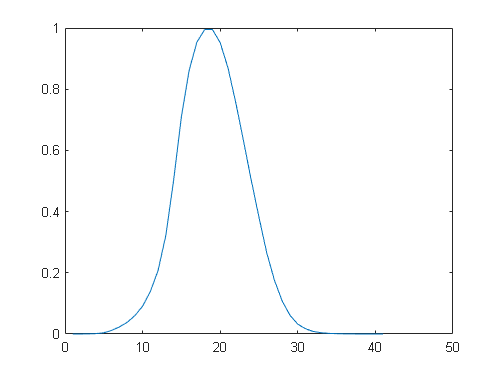

clf
plot(y)


XYZ_target = y * 0.01

